# Rekonstrukcja sygnału analogowego

clear all
input200Hz(1,:) = [0:0.005:0.1-0.005]; % time
input200Hz(2,:) = 230*sin(2*pi*50*input200Hz(1,:)); % values

output1kHz(1,:) = [0:0.0001:0.1-0.0001]; % time
output1kHz(2,:) = zeros(1,size(output1kHz, 2));

based on: 


$$\overset{\wedge }{x} =\sum_{n=-\infty }^{\infty } n\left(\mathrm{nT}\right)\mathrm{sinc}\left(\frac{\pi }{T}\left(t-\mathrm{nT}\right)\right)$$


for i=1:length(input200Hz(1,:))
   convo = input200Hz(2,i)...
       * sinc(200*(output1kHz(1,:)-input200Hz(1,i))); % jednostki
   output1kHz(2,:) = output1kHz(2,:) + convo;
end

plots:

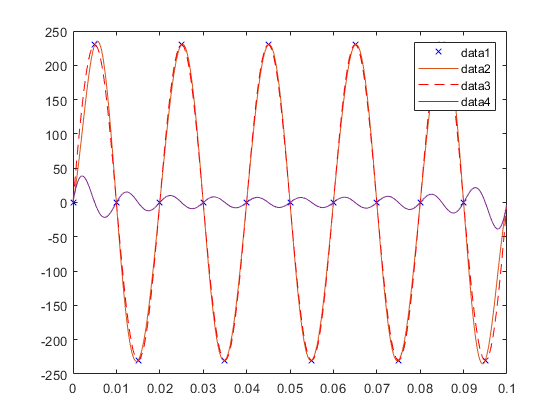

clf(1)
figure(1)
plot(input200Hz(1,:), input200Hz(2,:),'b x')
hold on 
plot(output1kHz(1,:), output1kHz(2,:))
plot(output1kHz(1,:), 230*sin(2*pi*50*output1kHz(1,:)), 'r--')
plot(output1kHz(1,:), 230*sin(2*pi*50*output1kHz(1,:))-output1kHz(2,:))
legend('show')